clear
close all
addpath("..\data\geojsonR01\")
addpath("..\data\matlabMobile\")

% センサーデータの読み込みとまとめ
load("himeji2shinosaka.mat")

sensor = synchronize(Acceleration,AngularVelocity,MagneticField,Orientation,Position,'union','previous');
sensor = rmmissing(sensor);
% 時間を初期値を0にする
sensor.Timestamp = sensor.Timestamp-sensor.Timestamp(1);

%センサーの時間切り出し
sensor = sensor(1:200000,:)

sensor = 200000×18 timetable
    Timestamp    X_Acceleration    Y_Acceleration    Z_Acceleration    X_AngularVelocity    Y_AngularVelocity    Z_AngularVelocity    X_MagneticField    Y_MagneticField    Z_MagneticField    X_Orientation    Y_Orientation    Z_Orientation    latitude    longitude    altitude    speed    course    hacc
    _________    ______________    ______________    ______________    _________________    _________________    _________________    _______________    _______________    _______________    _____________    _____________    _____________    ________    _________    ________    _____    ______    ____

    00:00:00        -0.13966          -0.10703           9.6308             0.00216             0.001051             -0.003185            -34.227            -17.518            -18.071           113.82          -0.19071         -0.26199        34.827      134.69       18.871       0      258.4      10 
    00:00:00        -0.13966          -0.10703           9.63

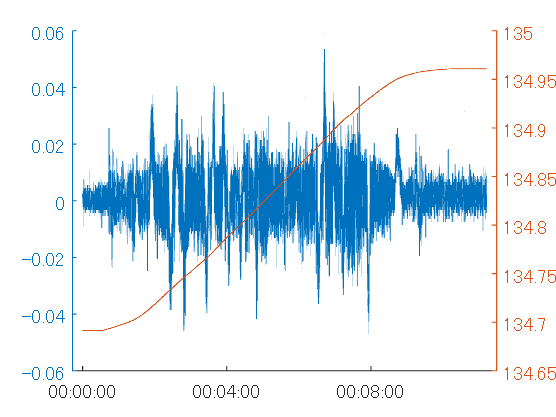

figure
hold on
yyaxis left
plot(sensor.Timestamp,sensor.Y_AngularVelocity)
yyaxis right
plot(sensor.Timestamp,sensor.longitude)
hold off

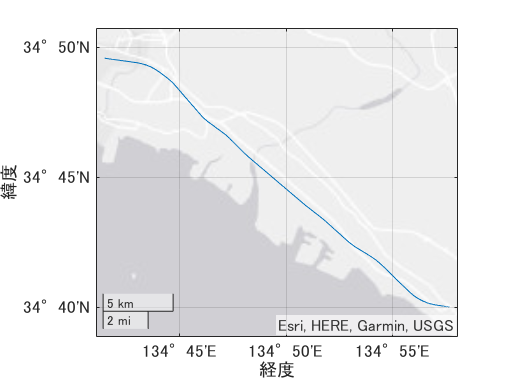

figure
geoplot(sensor.latitude,sensor.longitude)

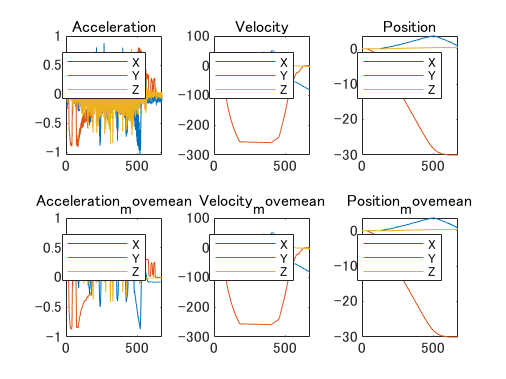

%　位置について
windowsize = 500;
% バイアスの確認
X_AccBias = mean(sensor.X_Acceleration(1:200,1));
Y_AccBias = mean(sensor.Y_Acceleration(1:200,1));
Z_AccBias = mean(sensor.Z_Acceleration(1:200,1));
% バイアスの修正
secondsTime = seconds(sensor.Timestamp);
X_Acc = sensor.X_Acceleration-X_AccBias;
Y_Acc = sensor.Y_Acceleration-Y_AccBias;
Z_Acc = sensor.Z_Acceleration-Z_AccBias;

figure
tiledlayout(2,3)
% 加速度
nexttile;
Acc = [X_Acc,Y_Acc,Z_Acc];
plot(secondsTime,Acc)
legend(["X","Y","Z"])
title("Acceleration")

% 速度
nexttile;
Vel = cumtrapz(secondsTime,Acc,1);
plot(secondsTime,Vel*3600/1000)
legend(["X","Y","Z"])
title("Velocity")

% 位置
nexttile;
Pos = cumtrapz(secondsTime,Vel,1);
plot(secondsTime,Pos/1000)
legend(["X","Y","Z"])
title("Position")

% 移動平均
% 加速度
nexttile;
movmeanAcc = movmean(Acc,windowsize);
plot(secondsTime,movmeanAcc)
legend(["X","Y","Z"])
title("Acceleration_movemean")

% 速度
nexttile;
movmeanVel = cumtrapz(secondsTime,movmeanAcc,1);
plot(secondsTime,Vel*3600/1000)
legend(["X","Y","Z"])
title("Velocity_movemean")

% 位置
nexttile;
movmeanPos = cumtrapz(secondsTime,movmeanVel,1);
plot(secondsTime,movmeanPos/1000)
legend(["X","Y","Z"])
title("Position_movemean")

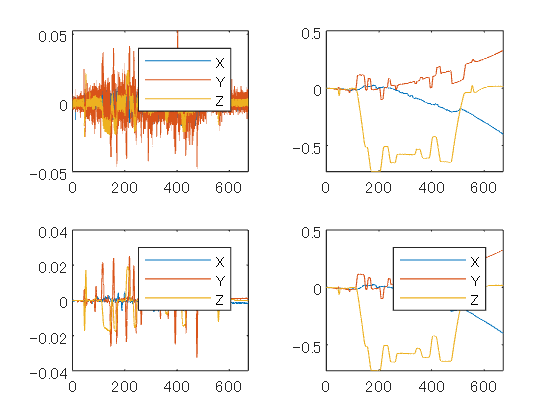

%%　角度についてのデータ
windowsize = 500;
% バイアスの確認
X_AngVelBias = mean(sensor.X_AngularVelocity(1:200,1));
Y_AngVelBias = mean(sensor.Y_AngularVelocity(1:200,1));
Z_AngVelBias = mean(sensor.Z_AngularVelocity(1:200,1));

% 角速度のバイアス修正
secondsTime = seconds(sensor.Timestamp);
X_AngVel = sensor.X_AngularVelocity-X_AngVelBias;
Y_AngVel = sensor.Y_AngularVelocity-Y_AngVelBias;
Z_AngVel = sensor.Z_AngularVelocity-Z_AngVelBias;


figure
tiledlayout(2,2);
nexttile;
AngVel = [X_AngVel,Y_AngVel,Z_AngVel];
plot(secondsTime,AngVel)
legend(["X","Y","Z"])

%角度変化
nexttile
Ang = cumtrapz(secondsTime,AngVel,1);
% 下の方法と同義
% X_Ang = cumtrapz(secondsTime,X_AngVel)
% Y_Ang = cumtrapz(secondsTime,Y_AngVel)
% Z_Ang = cumtrapz(secondsTime,Z_AngVel)
plot(secondsTime,Ang)

%移動平均のプロット
nexttile;
movmeanAngVel = movmean(AngVel,windowsize);
plot(secondsTime,movmeanAngVel)
legend(["X","Y","Z"])

nexttile;
movmeanAng = cumtrapz(secondsTime,movmeanAngVel,1);
plot(secondsTime,movmeanAng)
legend(["X","Y","Z"])

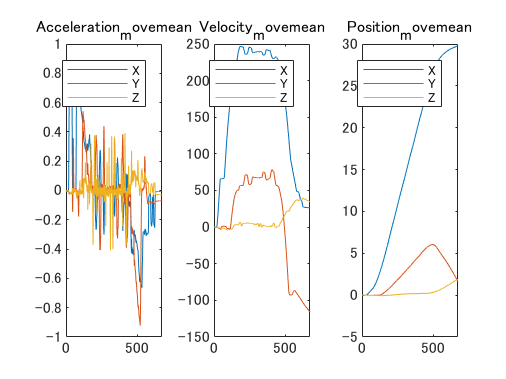

%　逆行列
rotmZYX = eul2rotm([-movmeanAng(:,3)+pi/2,-movmeanAng(:,2),-movmeanAng(:,1)]);
% a(:,:,1) = movmeanAcc;
movmeanAcc2 = pagemtimes(rotmZYX,permute(movmeanAcc,[2,3,1]));
movmeanAcc2 = permute(movmeanAcc2,[3,1,2]);

figure
tiledlayout(1,3);
% 加速度
nexttile;
plot(secondsTime,movmeanAcc2)
legend(["X","Y","Z"])
title("Acceleration_movemean")

% 速度
nexttile;
movmeanVel = cumtrapz(secondsTime,movmeanAcc2,1);
plot(secondsTime,movmeanVel*3600/1000)
legend(["X","Y","Z"])
title("Velocity_movemean")

% 位置
nexttile;
movmeanPos = cumtrapz(secondsTime,movmeanVel,1);
plot(secondsTime,movmeanPos/1000)
legend(["X","Y","Z"])
title("Position_movemean")

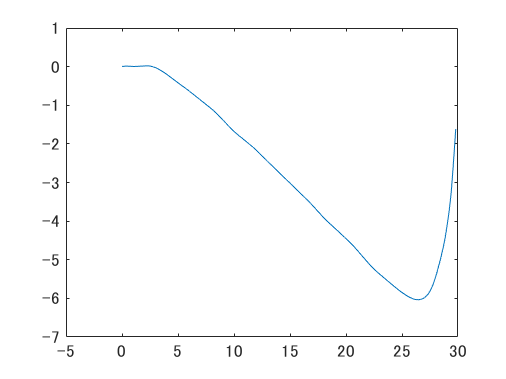


figure
plot(movmeanPos(:,1)/1000,-movmeanPos(:,2)/1000)

% ひゅべにの公式
% D = SQRT((Ay * M)^2 + (Ax * N * cos(P))^2)
sensor.longitude(1)

ans = 134.6915

sensor.latitude(1)

ans = 34.8265

sensor.longitude(end)

ans = 134.9610

sensor.latitude(end)

ans = 34.6670